Now that we have looked at the trial-averaged response, we have an idea of which orientations the neuron is most responsive to. To quantify the response of the cell to each orientation, we need to calculate the **orientation tuning curve**. This curve is generated by calculating the mean response of the neuron during the ON period, and comparing with its response during the OFF period.

To do this we will again start by extracting a 1x2880 DF/F vector for our one cell, and reshape this vector into a 3D matrix of size **SamplesPerOri x NumOrientations x NumTrials**.

load('DFF.mat');      

SamplesPerOri = 40;
NumOrientations = 12;
NumTrials = 6;
cell = 1; % this is the cell that we will analyze
        
dff_cell = DFF(cell,:); % extract dff trace for our cell
dff_reshaped = reshape(dff_cell,SamplesPerOri,NumOrientations,NumTrials);

Define ON and OFF periods as vectors extracted with appropriate indices. Extract the time-averaged response for each orientation and trial, and store them into `AveON` and `AveOFF`. Do NOT average over trials (`AveON `and `AveOFF`) will be 2D.

ON_period = 21:40;
OFF_period = 11:20;
        
AveON = mean(dff_reshaped(ON_period,:,:), 1);
AveOFF = mean(dff_reshaped(OFF_period,:,:), 1);

AveON = squeeze(AveON);
AveOFF = squeeze(AveOFF); 

Calculate the **mean **and **standard error** (over trials) of the `AveON` matrix, assigned to `ON_mean` and `ON_sem` respectively. These values will be used to plot the tuning curve, with error bars.

Orientations = 0:30:330;
        
ON_mean = mean(AveON,2);
ON_sem = std(AveON,[],2)/sqrt(NumTrials);

The `AveOFF` matrix will be used to estimate the baseline (i.e. spontaneous) activity. Calculate a single value by averaging over **both **dimensions (orientations and trials), assigning this value to `OFF_mean`. This baseline will then be plotted as a horizontal line,  given by the assignment of `OFF_line`.

OFF_mean = mean(AveOFF(:));
OFF_line = OFF_mean*ones(size(Orientations)); % this generates a baseline you can plot 

The tuning curve is now plotted.

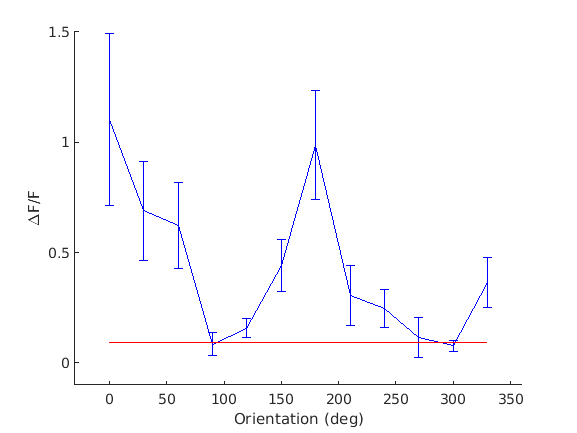

figure
hold on
errorbar(Orientations,ON_mean,ON_sem,'b') % plot ON tuning curve       
plot(Orientations,OFF_line,'r') % plot OFF spontaneous activity
xlim([-30 360])
ylim([min(ylim)-0.1, max(ylim)])
xlabel('Orientation (deg)')
ylabel('\DeltaF/F')